Notes:

**Identity Matrix** : all the elements of the identity matrix are zero except for those on the diagonal from the top left to the bottom right, which are all ones.

**Elementary Matrix** :  square matrix that is obtained by performing a single elementary row operation on an identity matrix. 

Determinant of A = det(A)

Gauss-Jordan elimination use rref to find reduce echelon

1. Use the **eye** function to create a 4 x 5 diagonal matrix called ***A*** with 7’s on the leading diagonal.

A = 7 * eye(4, 5)

A =      7     0     0     0     0
     0     7     0     0     0
     0     0     7     0     0
     0     0     0     7     0


2. Create a 3 x 3 elementary matrix called ***E*** that adds 3 of the 1st row to the 3rd row of a matrix. Test it with a random 3 x 3 matrix of integers

% Row 1 of A remains unchanged (1 * row1 + 0 * row2 + 0 * row3).
% Row 2 of A remains unchanged (0 * row1 + 1 * row2 + 0 * row3).
% Row 3 of A becomes (3 * row1 + 0 * row2 + 1 * row3).

E = [1, 0, 0; 0, 1, 0; 3, 0, 1];
M = randi([1, 10], 3, 3);
E

E =      1     0     0
     0     1     0
     3     0     1


M

M =      7     2     4
     2     8     7
     4     9     3


result = E*M

result =      7     2     4
     2     8     7
    25    15    15


3. Augment the test matrix from question 2 with a 3 x 3 identity matrix then use Matlab’s **rref** function to find it’s reduced echelon form.	

refForm = rref(result)

refForm =      1     0     0
     0     1     0
     0     0     1


refForm

refForm =      1     0     0
     0     1     0
     0     0     1


4. Create the coefficient matrix for the following linear system, check that its determinant is not 0, then calculate the solution using the inverse matrix method (*hint:* you can find the inverse of a matrix with the **inv** function).

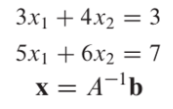

A = [3, 4; 5, 6;]

A =      3     4
     5     6


b = [3; 7]

b =      3
     7


disp(det(A))

   -2.0000



invA = inv(A)

invA =    -3.0000    2.0000
    2.5000   -1.5000


x = inv(A) * b

x =     5.0000
   -3.0000



disp("solution : ")

solution : 


disp(x)

    5.0000
   -3.0000



5. Solve the system above but using Matlab’s left-division operator.

A = [3, 4; 5, 6];
b = [3; 7];

x = A \ b;

disp("Solution:");

Solution:


disp(x);

    5.0000
   -3.0000



6. There are 3 reactors linked by pipes as shown below. The rate of transfer of chemicals through each pipe is equal to a flow rate (Q, with units of cubic meters per ­second) multiplied by the concentration of the reactor from which the flow originates (c, with units of milligrams per cubic meter). If the system is at a steady state, the transfer into each reactor will balance the transfer out. Develop mass-balance equations for the reactors and solve the three simultaneous linear algebraic equations for their concentrations.

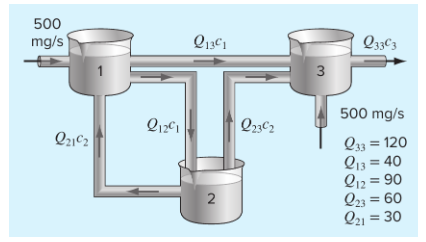

% rate of transfer = Q * c
% Input Mass − Output Mass + Generation − Consumption = Accumulation
% x = inv(A) * b system of linear equations being solved using matrix algebra

Q33 = 120;
Q13 = 40;
Q12 = 90;
Q23 = 60;
Q21 = 30;

% Bucket 1 : 500 + Q21C2 = Q13C1 + Q12C1       
% Bucket 2 : Q21C2 + Q23C2 = Q12C1              
% Bucket 3 : Q23C2 + 500 = Q33C3 

% Bucket 1 : Q21C2 - Q13C1 - Q12C1 = -500
% Bucket 2 : Q21C2 + Q23C2 - Q12C1 = 0
% Bucket 3 : Q23C2 - Q33C3 = -500

MatrixR = [90, 40, 90; 30, 60, 90; 60, 120, 0]

MatrixR =     90    40    90
    30    60    90
    60   120     0


MatrixL = [-500; 0; -500]

MatrixL =   -500
     0
  -500



disp(det(MatrixR))

     -756000



invR = inv(MatrixR)

invR =     0.0143   -0.0143    0.0024
   -0.0071    0.0071    0.0071
         0    0.0111   -0.0056


c = invR * MatrixL

c =    -8.3333
         0
    2.7778


disp(c)

   -8.3333
         0
    2.7778



7. Use Matlab’s **fsolve** function to find the roots of the system. Since there are infinite solutions you do not need to find every root. Just locate and plot those given in the default window. Plotting is always a good idea to give you an idea of how many roots you are looking for and where to make the initial guesses. Use the **fimplicit** function to plot these implicit functions on the same graph. Define a function at the end of your script closed with keyword **end** that holds the system of equations. Advanced users can also use the ginput() function to pick starting initial guesses.

f1 = @(x, y) exp(x * y) - y^2;
f2 = @(x, y) cos(x + y);
roots = []


roots =

     []




grid on
fimplicit(f1, [-5, 5], 'b')

hold on
fimplicit(f2, [-5, 5], 'r')


% combine the 2 function into 1 single vector value equation
system_eqns = @(vars) [f1(vars(1), vars(2)); f2(vars(1), vars(2))];

%click on where the two function intersect
%initial_guess = ginput(6);
initial_guess = [-1, -5; 0, -1; -3, 0; 1, 0.5; 2.5, -0.5; 2, 3.5];

for n = 1:length(initial_guess)
    root = fsolve(system_eqns, initial_guess(n, :));
    roots = [roots; root];
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 


roots

roots =    -0.6922   -4.0202
   -0.3387   -1.2320
   -2.1254    0.5546
    0.3387    1.2320
    2.1254   -0.5546
    0.6922    4.0202


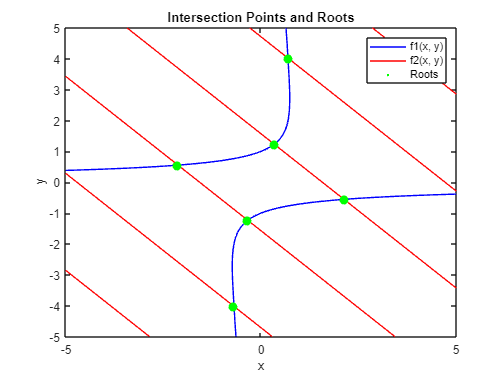

scatter(roots(:, 1), roots(:, 2), 500, 'g', '.');
xlabel('x');
ylabel('y');
title('Intersection Points and Roots');
legend('f1(x, y)', 'f2(x, y)', 'Roots');
hold off;

8. Find a root of the following system. Check your solution.

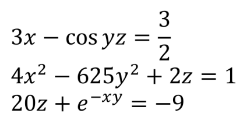

f1 = @(x, y, z) 3*x - cos(y*z) - 3/2;
f2 = @(x, y, z) 4*x^2 - 625*y^2 + 2*z - 1;
f3 = @(x, y, z) 20*z + exp(-x*y) + 9;

system_eqns = @(vars) [f1(vars(1), vars(2), vars(3)); 
                       f2(vars(1), vars(2), vars(3));
                       f3(vars(1), vars(2), vars(3))];

[roots, fval, exitflag] = fsolve(system_eqns, [0, 0, 0])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


roots =     0.8333   -0.0352   -0.5015


fval = 1.0e-12 *

         0
   -0.1357
         0


exitflag = 1


%x_sol is the output variable where the solution to the system of equations is stored. x_sol contains the values of x, y, and z.
%fval is the output variable that contains the values of the equations evaluated at the solution x_sol.
%exitflag is the output variable that indicates the exit condition of the solver. 
% A positive exitflag typically indicates a successful convergence to a solution, while a negative value may indicate issues or failure to find a solution.

x = roots(1)

x = 0.8333

y = roots(2)

y = -0.0352

z = roots(3)

z = -0.5015


% Check the solution
if exitflag > 0
    fprintf('Root found:\n');
    fprintf('x = %.6f\n', x);
    fprintf('y = %.6f\n', y);
    fprintf('z = %.6f\n', z);
else
    fprintf('No root found or an error occurred.\n');
end

Root found:


x = 0.833281


y = -0.035201


z = -0.501488



fprintf("f1 solution = %.8f\n", f1(x, y, z))

f1 solution = 0.00000000


fprintf("f2 solution = %.8f\n", f2(x, y, z))

f2 solution = -0.00000000


fprintf("f3 solution = %.8f\n", f3(x, y, z))

f3 solution = 0.00000000


9. Write a script that uses the Newton Method for Nonlinear Systems to solve the following nonlinear system. Try to find the roots of the system with your script. Remember you’ll have to compute the Jacobian yourself by hand for now in order to put it into your script.'

% delta : difference between the current guess and the improved guess
% using J\F instead of -J\F would lead the algorithm away from the roots,
% so J\F is not use in root finding

% Define the symbolic variables
syms x y;

% Define the equations
eq1 = 3*x^2 + 2*y^2 - 25;
eq2 = 2*x^2 - y - 15;

% Create the vector-valued function F
F = [eq1; eq2];

% Initialize the roots array
roots = [];

% Iterate over different initial guesses
initial_guesses = [1, 1; -1, 1; -1, -1; 1, -1];
for i = 1:size(initial_guesses, 1)
    x0 = initial_guesses(i, :)';
    
    % Tolerance for convergence
    tolerance = 1e-6;

    % Maximum number of iterations
    maxIterations = 100;

    % Initialize the Jacobian matrix
    Jacobian = jacobian(F, [x, y]);

    % Convert the symbolic Jacobian matrix to a function handle
    Jacobian_func = matlabFunction(Jacobian, 'Vars', [x, y]);

    % Start the Newton-Raphson iteration
    for iter = 1:maxIterations
        % Calculate the value of F and Jacobian at the current point
        F_value = double(subs(F, [x; y], x0));
        J_value = Jacobian_func(x0(1), x0(2));

        % Solve the linear system to get the update
        delta = -J_value \ F_value;

        % Update the current point
        x0 = x0 + delta;

        % Check for convergence
        if norm(delta) < tolerance
            roots = [roots; x0'];
            break;
        end
    end
end

% Display the roots
fprintf('The roots are:\n');

The roots are:


disp(roots);

    2.8111    0.8042
   -2.8111    0.8042
   -2.5929   -1.5542
    2.5929   -1.5542



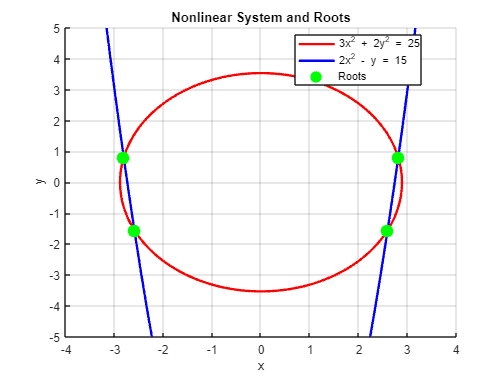


% Create a plot
figure;
hold on;

% Plot the equations
fimplicit(eq1, 'r', 'LineWidth', 2);
fimplicit(eq2, 'b', 'LineWidth', 2);

% Plot the roots
plot(roots(:, 1), roots(:, 2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');

xlabel('x');
ylabel('y');
title('Nonlinear System and Roots');
legend('3x^2 + 2y^2 = 25', '2x^2 - y = 15', 'Roots', 'Location', 'Best');
grid on;

hold off;

10. Write a script that reduces a 3 x 3 matrix to an echelon form (don’t worry about pivoting). Test it on the following matrix:

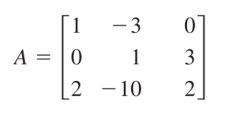

% Define the input matrix
A = [1, -3, 0; 0, 1, 3; 2, -10, 2];

% size of matrix
[m, n] = size(A)

m = 3

n = 3


disp("A matrix : ")

A matrix : 


disp(A)

     1    -3     0
     0     1     3
     2   -10     2




% Loop over each column
for col = 1:n
    % Find the first non-zero element (pivot) in the current column
    for row = col:m
        if A(row, col) ~= 0
            break;
        end
    end

    % Swap the current row with the row containing the pivot
    if A(row, col) ~= 0
        A([col, row], :) = A([row, col], :);
    end
    
    % Make all the elements below the pivot zero
    for row = col+1:m
        factor = A(row, col) / A(col, col);
        A(row, :) = A(row, :) - factor * A(col, :);
    end
end

% Display the row echelon form
disp('Row Echelon Form:');

Row Echelon Form:


disp(A);

     1    -3     0
     0     1     3
     0     0    14



11. Write a script that reduces the above matrix to reduced echelon form (RREF)

rrefA = rref(A)

rrefA =      1     0     0
     0     1     0
     0     0     1


disp("RREF form of A : ")

RREF form of A : 


disp(rrefA)

     1     0     0
     0     1     0
     0     0     1



12. Write a script that finds the LU factorisation of the matrix ***A*** in question 10 using Gaussian elimination to find ***U*** and the formulae given in lecture notes 6 to find ***L***.

% Gaussian elimination is used to transform a matrix into its row echelon form (REF)
% which is a step towards achieving its reduced row echelon form (RREF).
% U is an upper triangular matrix where all elements below the main
% diagonal are zero, diagonal and elements above the diagonal in U are the same as those in the original matrix A.
% L is a lower triangular matrix where all elements above the main diagonal
% are zero, diagonal elements are all ones.

A = [1, -3, 0; 0, 1, 3; 2, -10, 2];
% Get the size of the matrix
[m, n] = size(A);

% Initialize matrices L and U
L = eye(m);  % Initialize L as identity matrix
U = A;        % Initialize U as A

% Perform Gaussian elimination to get U and update L
for col = 1:n
    % Perform row operations to eliminate elements below the pivot
    for row = col+1:m
        factor = U(row, col) / U(col, col); % L is updated using the formula factor = U(row, col) / U(col, col);, 
        L(row, col) = factor;  % Store the multiplier in L
        U(row, :) = U(row, :) - factor * U(col, :);  % U is updated using row operations to eliminate elements below the pivot
    end
end

% Display matrices L and U
disp('Matrix L:');

Matrix L:


disp(L);

     1     0     0
     0     1     0
     2    -4     1



disp('Matrix U:');

Matrix U:


disp(U);

     1    -3     0
     0     1     3
     0     0    14



13. Solve the following system using LU factorisation by finding ***L*** and ***U*** as in question 12

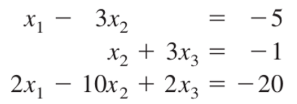

% Coefficient matrix
A = [1, -3, 0;
     0, 1, 3;
     2, -10, 2];

% Right-hand side vector
b = [-5; -1; -20];

% Get the size of the matrix
[m, n] = size(A);

% Initialize matrices L and U
L = eye(m);  % Initialize L as identity matrix
U = A;        % Initialize U as A

% Perform Gaussian elimination to get U and update L
for col = 1:n
    % Perform row operations to eliminate elements below the pivot
    for row = col+1:m
        factor = U(row, col) / U(col, col);
        L(row, col) = factor;  % Store the multiplier in L
        U(row, :) = U(row, :) - factor * U(col, :);
    end
end

% Solve Ly = Pb to find y by forward substitution
y = zeros(m, 1);
for i = 1:m
    y(i) = (b(i) - L(i, 1:i-1) * y(1:i-1)) / L(i, i);
end

% Solve Ux = y to find the solution x by backward substitution
x = zeros(m, 1);
for i = m:-1:1
    x(i) = (y(i) - U(i, i+1:m) * x(i+1:m)) / U(i, i);
end

% Display the solution vector x
fprintf('Solution vector x:\n');

Solution vector x:


disp(x);

     1
     2
    -1



14. Solve the following system using LU factorisation by finding ***L*** and ***U*** as in question 13.

% Coefficient matrix
A = [1, -3, 0;
     0, 1, 3;
     2, -10, 2];

% Right-hand side vector
b = [-5; -1; -20];

% Perform LU factorization with pivoting
[L, U, P] = lu(A);

% Solve Lc = Pb or Ly = b
c = L \ (P * b);

% Solve Ux = c or Ux = y
x = U \ c;

% Display the solution
disp('Solution:');

Solution:


disp(x);

     1
     2
    -1



15. **Challenge Problem**

Write your own function file that calculates the inverse of a square matrix. The input should be a square matrix of any size and it should have sufficient checks to make sure the user inputs an invertible matrix or return an error/warning.	

% Define the input matrix
A = [2, 1; 4, 3];

% Calculate the inverse using the custom function
inverse_A = calculate_inverse(A);

% Display the inverse matrix
fprintf('Inverse of A:\n');

Inverse of A:


disp(inverse_A);

    1.5000   -0.5000
   -2.0000    1.0000

